# Show Thermoeconomic State Demo

Use ThermoeconomicState function to obtain the exergy balances and Table FP

#### Read the Data Model

file="D:\Documents\Termoeconomia\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Select the State to display

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(5));

#### Get the exergy values 

res=ThermoeconomicState(data,'State',State,'Show',true);

Flows Exergy Table

Key   From    To             B(kW)
———————————————————————————————————
B1    BLR_P1  TRB_F1        83.570
B2    TRB_F1  IHE_F1        17.900
B3    IHE_F1  CND_F1        17.900
B4    CND_F1  PMP_P1         5.784
B5    PMP_P1  IHE_P1         7.877
B6    IHE_P1  BLR_P1         7.877
QBLR  ENV_R1  BLR_F1       106.900
WP    TRB_P1  PMP_F1         2.447
WN    TRB_P1  ENV_O1        50.000
QCND  CND_P1  ENV_W1        12.116


Productive Groups Exergy Table

Key            E(kW)      ET(kW)
—————————————————————————————————
BLR_F1       106.900     106.900
BLR_P1        75.693      83.570
TRB_F1        65.670      83.570
TRB_P1        52.447      52.447
IHE_F1         0.000      17.900
IHE_P1         0.000       7.877
PMP_F1         2.447       2.447
PMP_P1         2.093       7.877
CND_F1        12.116      17.900
CND_P1        12.116      12.116
ENV_R1       106.900     106.900
ENV_O1        50.000      50.000
ENV_W1        12.116      12.116


Processes Exergy Table

Key

#### Show the Diagram FP

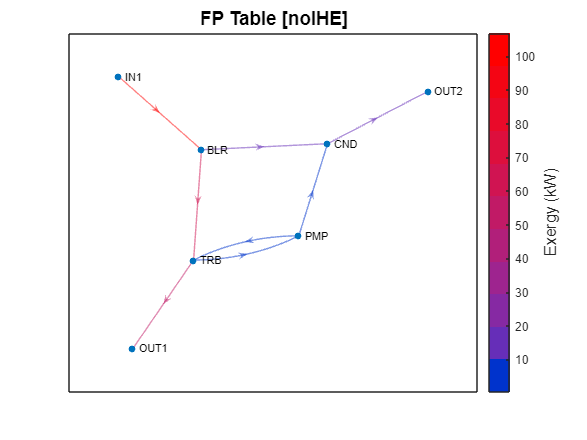

showGraph(res,'tfp')